### 1.1. Preprocessing Steps

EEG.history

ans =     '
     EEG.etc.eeglabvers = '2021.1'; % this tracks which version of EEGLAB is being used, you may ignore it
     EEG = eeg_checkset( EEG );
     EEG = eeg_checkset( EEG );
     EEG = pop_reref( EEG, 64,'keepref','on');
     EEG = eeg_checkset( EEG );
     pop_eegplot( EEG, 1, 1, 1);
     EEG.etc.eeglabvers = '2022.0'; % this tracks which version of EEGLAB is being used, you may ignore it
     EEG = eeg_checkset( EEG );
     EEG = pop_eegfiltnew(EEG, 'locutoff',0.1,'hicutoff',100,'plotfreqz',1);
     EEG = eeg_checkset( EEG );
     EEG = pop_reref( EEG, []);
     EEG = eeg_checkset( EEG );
     EEG = pop_eegfiltnew(EEG, 'locutoff',49,'hicutoff',51,'revfilt',1,'plotfreqz',1);
     EEG = eeg_checkset( EEG );
     EEG = pop_epoch( EEG, {  'E  1'  }, [-0.1           1], 'newname', '38 resampled epochs', 'epochinfo', 'yes');
     EEG = eeg_checkset( EEG );
     EEG = pop_rmbase( EEG, [-100 0] ,[]);
     EEG = eeg_checkset( EEG );'


### 1.2. Representational Dissimilarity Matrices(RDMs)

#### 1.2.1.

events = readtable('data\events.csv');
events = events((events.object=="chair" | events.object=="dog" | events.object=="face"),["object" "eventnumber"])

events = 36×2 table
     object      eventnumber
    _________    ___________

    {'chair'}         86    
    {'dog'  }        359    
    {'face' }        590    
    {'chair'}       2161    
    {'face' }       2944    
    {'dog'  }       3226    
    {'dog'  }       3717    
    {'chair'}       3944    
    {'face' }       4363    
    {'chair'}       5637    
    {'face' }       5833    
    {'dog'  }       7233    
    {'dog'  }       8343    
    {'chair'}       8348    
    {'face' }       8581    
    {'face' }       9370    


chair = table2array(events((events.object=="chair"),"eventnumber"));
dog = table2array(events((events.object=="dog"),"eventnumber"));
face = table2array(events((events.object=="face"),"eventnumber"));

face_data = data(:,:,face);
chair_data = data(:,:,chair);
dog_data = data(:,:,dog);

#### 1.2.2.

avg_face_matrix = get_averega_matrix(face_data,200)

avg_face_matrix =    -6.0252   -0.9644   -4.8565    3.4102   -3.2853  -11.5538    4.6378   14.7465   -8.1914   -6.9545   11.2858   10.9816    6.9583    2.6419    7.3010    3.6550    1.4156    0.6806    1.8774    7.6765   13.5151    4.7329   -9.1959    9.8772   -0.8707  -15.0165   -7.4316  -10.0117   -3.0551   -1.1393   11.6687   -4.0560    2.8651   -5.7836   -7.3010  -10.0562   -2.4831    7.0436    8.5095   -1.9238   -3.3625    5.2354   14.1527   10.6193   10.6510    1.7660    0.0636   -3.3497   -3.3700    4.2632
    2.7675    7.5251    3.7497    3.6714    2.2534   -3.3415   -3.4247   40.8542   -5.9818   -7.9404  -10.9714   -4.9784  -12.8058   -6.2757   -3.0657    0.9821    5.4618   -1.4825   -1.0332    3.2343   -1.9418    2.8282   -1.1219    1.7338    2.5915   -2.6711    2.5819    7.3158    6.6368    0.7421   -0.3229   10.2843    2.5646    5.6940    0.0765   -2.8157   -3.6465   -2.3766   -7.8474   -6.5555   -4.0617  -10.7429   -5.1919   -0.0456   -8.9300   -5.3911    0.7907    6.5665 

avg_chair_matrix = get_averega_matrix(chair_data,200)

avg_chair_matrix =    -1.8496   -6.1173   -3.0303   -7.8057   -1.4468    2.2392   -5.1328   -6.3644    3.3903    3.1392   -1.4367   -0.8452    8.8415   15.6019    7.7749   10.1423   16.0742   19.6604   10.2740    0.5196   -4.6030   -4.4400    5.0050   -8.3536   -9.9310   -5.9638   -7.5383   -8.8433   -8.5824  -11.5363  -12.7662   -5.8706   -9.0653   -1.9636    1.8287    5.2233   -1.2094   -7.9569   -3.4567    1.4220    9.3650    2.9990   -4.7385   -0.9486    2.6769   12.2602   16.5735   19.4932   19.8526    5.2365
    4.2857    5.4857    4.2428    6.2189    6.5514    2.5942    6.3692 -241.3981   -0.8329    1.0779    1.5887   -2.6117    7.5281    6.1091   -1.8594   -8.6261   -9.6216   -7.7374   -4.8852   -2.7172    3.2087    6.6521    3.6432    8.0002   10.6054    7.8643   10.1486    9.6116   11.8878   10.5899    9.1256    3.3068    8.4891    5.6747   -2.2702   -0.3572    2.7370   10.3177    4.0419    4.9859    3.2786    3.4986    2.0346   -4.5192   -0.6048   16.0125   -0.8012   -7.5796

avg_dog_matrix = get_averega_matrix(dog_data,200)

avg_dog_matrix =     4.4563   10.8173   17.0014    8.7135    8.3274    5.5175    5.4371   -2.5035    6.9036    8.5858    1.4032   -3.9191    2.7930   -1.5697   -1.7838  -11.2640  -17.0295  -18.9072  -13.8339  -11.6156   -9.6984   -6.2202   -2.2184   -3.8693    4.4206    4.6152    5.7387    7.2120   10.6273    7.1699    0.5679   10.0541    6.7041    7.6399    5.2451    6.9717    6.1471    3.2615    2.1434    1.4795    7.9957    6.4911   -4.3304  -11.0623    1.8970   -2.5422   -5.1835  -12.0085  -17.6200  -11.7955
    0.1699   -2.8692   -1.8089   -2.1470   -1.2637    5.4107    0.5537   40.6148    9.0883   10.9865    0.4947   -4.7875   -1.4739    2.2187    1.8363   -7.1654   -9.3763  -11.1290  -10.5341   -6.1673   -2.9363    0.8286   -3.1497   -0.7393    3.4280    4.4909    2.1296    4.1180    1.1946   -0.0656   -3.9953   -0.2881   -2.6083   -5.3337   -3.5291    6.0243    3.1768   -0.1134    1.4995    4.1716    6.8604    2.0463   -1.3184   -9.0530   -2.4106    2.6767    0.4029   -1.3420  

channel_1


         0    1.1189    0.9580
    1.1189         0    0.8042
    0.9580    0.8042         0



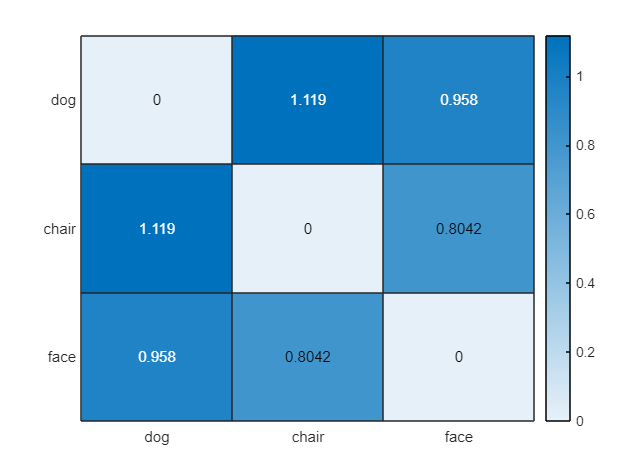

channel_2


         0    1.2098    1.1329
    1.2098         0    1.1888
    1.1329    1.1888         0



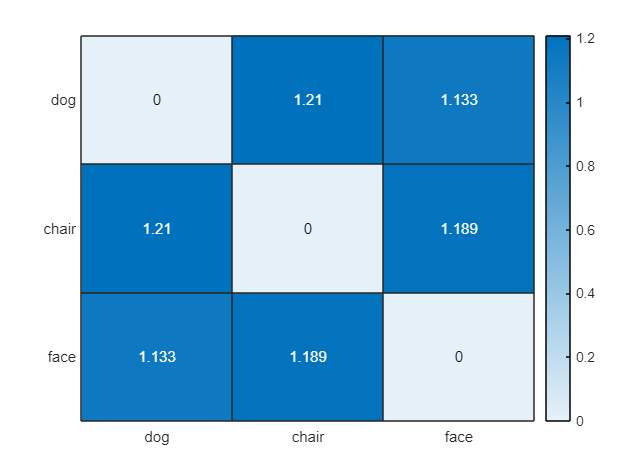

channel_3


         0    1.2448    1.0839
    1.2448         0    1.2028
    1.0839    1.2028         0



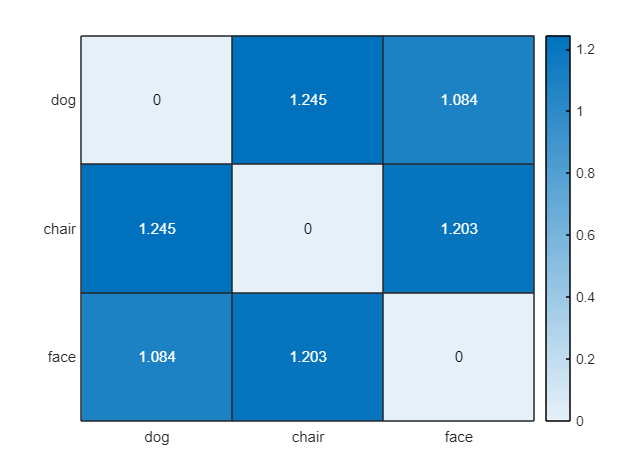

channel_4


         0    1.1888    0.7902
    1.1888         0    1.2727
    0.7902    1.2727         0



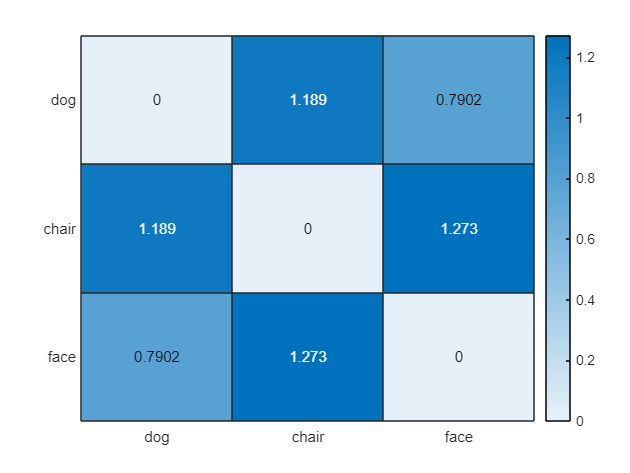

channel_5


         0    1.4196    0.6993
    1.4196         0    1.5455
    0.6993    1.5455         0



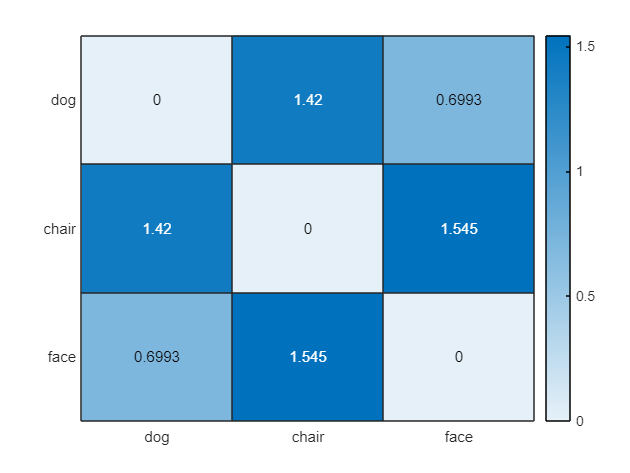

channel_6


         0    0.6224    1.2937
    0.6224         0    1.0070
    1.2937    1.0070         0



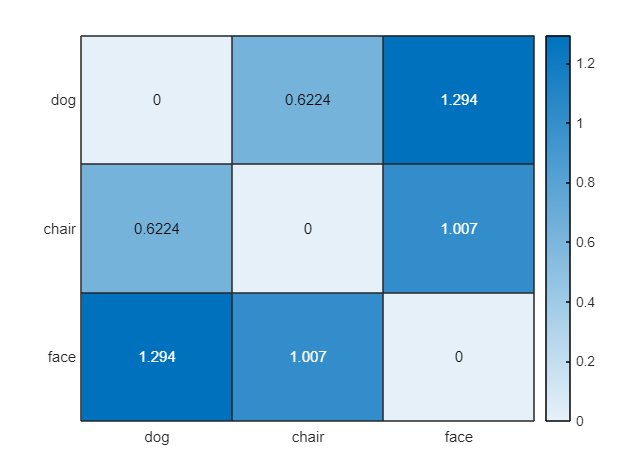

channel_7


         0    1.2587    0.8112
    1.2587         0    1.4406
    0.8112    1.4406         0



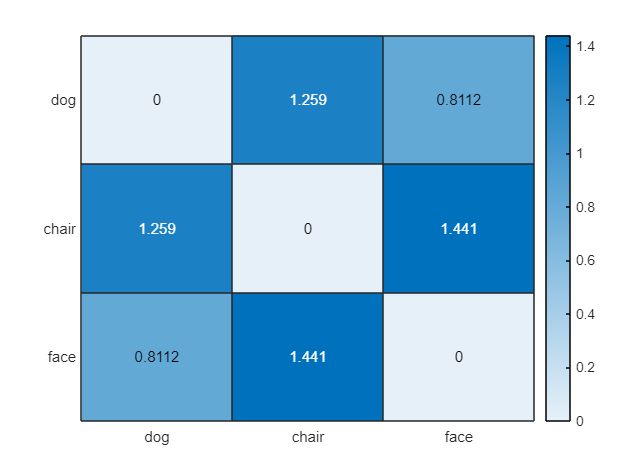

channel_8


         0    1.0629    0.8392
    1.0629         0    1.2517
    0.8392    1.2517         0



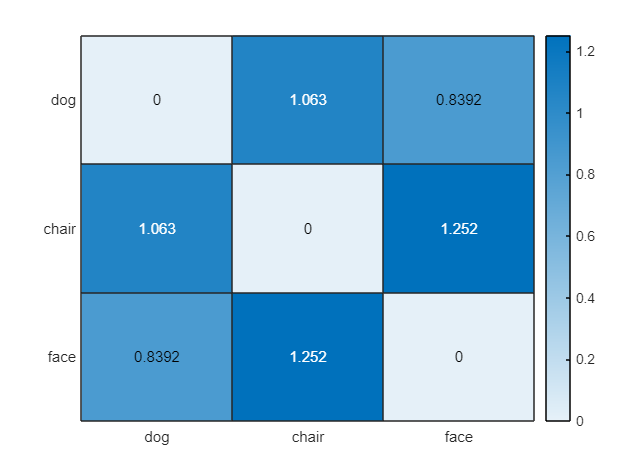

channel_9


         0    1.0000    1.3846
    1.0000         0    1.0769
    1.3846    1.0769         0



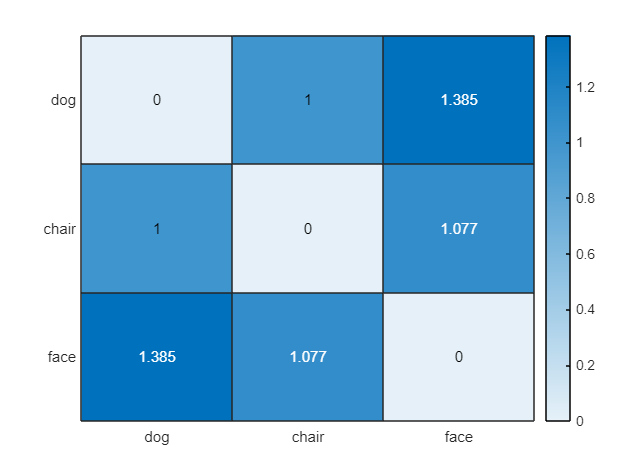

channel_10


         0    1.2168    1.2308
    1.2168         0    1.1608
    1.2308    1.1608         0



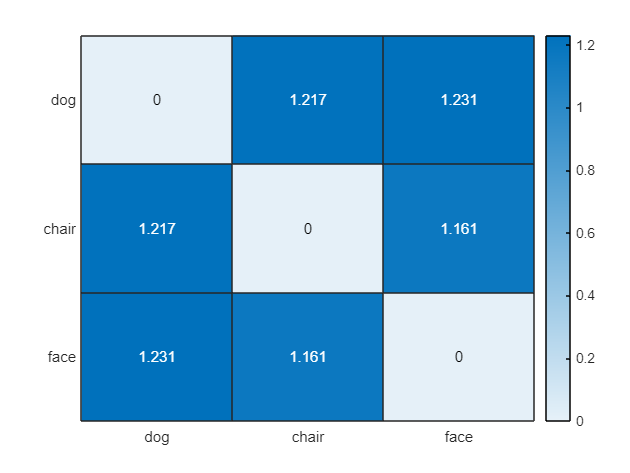

channel_11


         0    1.3007    0.9860
    1.3007         0    1.3776
    0.9860    1.3776         0



channel_12


         0    1.3147    0.5874
    1.3147         0    0.9790
    0.5874    0.9790         0



channel_13


         0    0.8671    0.6853
    0.8671         0    1.3986
    0.6853    1.3986         0



channel_14


         0    0.9371    0.9510
    0.9371         0    1.3706
    0.9510    1.3706         0



channel_15


         0    1.2587    0.6084
    1.2587         0    1.0839
    0.6084    1.0839         0



channel_16


         0    1.3566    0.6643
    1.3566         0    1.1329
    0.6643    1.1329         0



channel_17


         0    1.0490    1.0769
    1.0490         0    1.2517
    1.0769    1.2517         0



channel_18


         0    1.2448    1.4825
    1.2448         0    0.6154
    1.4825    0.6154         0



channel_19


         0    1.2587    1.4895
    1.2587         0    0.6713
    1.4895    0.6713         0



channel_20


         0    1.3217    1.3846
    1.3217         0    1.3636
    1.3846    1.3636         0



channel_21


         0    1.3217    1.3636
    1.3217         0    1.3916
    1.3636    1.3916         0



channel_22


         0    1.5455    1.0769
    1.5455         0    0.9301
    1.0769    0.9301         0



channel_23


         0    1.1678    1.1189
    1.1678         0    1.1329
    1.1189    1.1329         0



channel_24


         0    0.9301    1.0559
    0.9301         0    1.4056
    1.0559    1.4056         0



channel_25


         0    0.9161    1.1259
    0.9161         0    0.7343
    1.1259    0.7343         0



channel_26


         0    1.1119    1.4266
    1.1119         0    0.4545
    1.4266    0.4545         0



channel_27


         0    0.9720    1.0210
    0.9720         0    0.3986
    1.0210    0.3986         0



channel_28


         0    1.4126    1.2308
    1.4126         0    0.4126
    1.2308    0.4126         0



channel_29


         0    1.2587    1.1538
    1.2587         0    0.5874
    1.1538    0.5874         0



channel_30


         0    1.2797    1.0979
    1.2797         0    0.9091
    1.0979    0.9091         0



channel_31


         0    1.4685    1.0350
    1.4685         0    1.1399
    1.0350    1.1399         0



channel_32


         0    1.3846    1.0979
    1.3846         0    0.8531
    1.0979    0.8531         0



channel_33


         0    1.1888    0.8671
    1.1888         0    1.0490
    0.8671    1.0490         0



channel_34


         0    1.3916    0.8881
    1.3916         0    1.1399
    0.8881    1.1399         0



channel_35


         0    1.0769    1.1399
    1.0769         0    0.6853
    1.1399    0.6853         0



channel_36


         0    1.1399    1.4266
    1.1399         0    1.0420
    1.4266    1.0420         0



channel_37


         0    1.1329    1.0839
    1.1329         0    1.5664
    1.0839    1.5664         0



channel_38


         0    1.2517    0.9231
    1.2517         0    1.4126
    0.9231    1.4126         0



channel_39


         0    0.7902    1.2168
    0.7902         0    1.4126
    1.2168    1.4126         0



channel_40


         0    1.1538    1.5594
    1.1538         0    1.1469
    1.5594    1.1469         0



channel_41


         0    0.8671    1.2797
    0.8671         0    1.2797
    1.2797    1.2797         0



channel_42


         0    1.0070    0.9091
    1.0070         0    1.4476
    0.9091    1.4476         0



channel_43


         0    0.8671    1.1329
    0.8671         0    1.4685
    1.1329    1.4685         0



channel_44


         0    1.0909    1.1189
    1.0909         0    1.3776
    1.1189    1.3776         0



channel_45


         0    0.9231    0.3916
    0.9231         0    1.0000
    0.3916    1.0000         0



channel_46


         0    0.7972    1.0070
    0.7972         0    1.2937
    1.0070    1.2937         0



channel_47


         0    1.1329    0.6014
    1.1329         0    1.3147
    0.6014    1.3147         0



channel_48


         0    1.2168    0.3986
    1.2168         0    1.3916
    0.3986    1.3916         0



channel_49


         0    1.0140    0.8042
    1.0140         0    0.9650
    0.8042    0.9650         0



channel_50


         0    1.3986    1.5175
    1.3986         0    0.8741
    1.5175    0.8741         0



channel_51


         0    1.2657    1.5315
    1.2657         0    0.7972
    1.5315    0.7972         0



channel_52


         0    1.2168    1.1329
    1.2168         0    1.2168
    1.1329    1.2168         0



channel_53


         0    1.5175    1.1329
    1.5175         0    0.8811
    1.1329    0.8811         0



channel_54


         0    1.3706    1.2028
    1.3706         0    1.4476
    1.2028    1.4476         0



channel_55


         0    1.1329    1.5944
    1.1329         0    1.3776
    1.5944    1.3776         0



channel_56


         0    0.8042    0.6923
    0.8042         0    1.0280
    0.6923    1.0280         0



channel_57


         0    1.3287    1.3427
    1.3287         0    0.8881
    1.3427    0.8881         0



channel_58


         0    1.1189    1.5385
    1.1189         0    0.8601
    1.5385    0.8601         0



channel_59


         0    0.8392    1.3776
    0.8392         0    0.5245
    1.3776    0.5245         0



channel_60


         0    1.3846    1.0350
    1.3846         0    1.3776
    1.0350    1.3776         0



channel_61


         0    1.0979    0.9371
    1.0979         0    0.6993
    0.9371    0.6993         0



channel_62


         0    1.2168    1.3357
    1.2168         0    0.4545
    1.3357    0.4545         0



channel_63


         0    1.2028    1.2937
    1.2028         0    0.5734
    1.2937    0.5734         0



channel_64


         0    1.0909    1.2587
    1.0909         0    0.7832
    1.2587    0.7832         0



map = containers.Map('KeyType','char','ValueType','any');
map("dog") = avg_dog_matrix;
map("chair") = avg_chair_matrix;
map("face") = avg_face_matrix;
for i = 1:64
    disp(strcat('channel_',num2str(i)));
    matrix = channel_rdm(map,i);
    disp(matrix)
    if(i<11)
        values = {'dog','chair','face'};
        figure
        heatmap(values,values,matrix);
    end
end

#### 1.2.3.

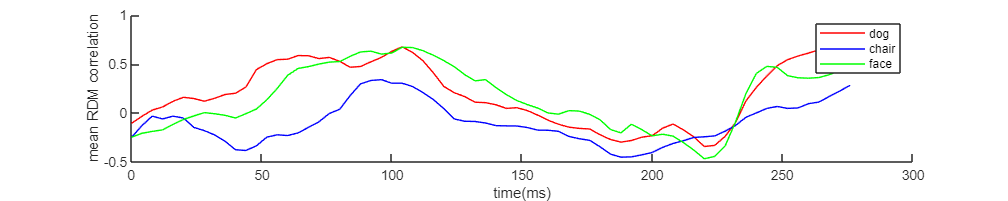

objects_map = containers.Map('KeyType','char','ValueType','any');
objects_map("dog") = dog_data;
objects_map("chair") = chair_data;
objects_map("face") = face_data;

dog_rsa = get_rsa(objects_map,"dog");
chair_rsa = get_rsa(objects_map,"chair");
face_rsa = get_rsa(objects_map,"face");
time = 4*(26:95)-104;
f = figure;
f.Position = [10 10 1000 200];
hold on
plot(time,dog_rsa,'r');
plot(time,chair_rsa,'b')
plot(time,face_rsa,'g')
xlabel('time(ms)')
ylabel('mean RDM correlation')
legend("dog","chair","face")

function rsa_matrix = get_rsa(objects_map,object)
    objects_list = ["dog","face","chair"]; 
    others = objects_list(objects_list~=object);
    goal = objects_map(object);
    object1 = objects_map(others(1));
    object2 = objects_map(others(2));
    others = cat(3,object1,object2);
    rsa_matrix = zeros(70,1);
    i = 1;
    for t_idx = 26:95
        goal_mean = mean(goal(:,t_idx-6:t_idx+6,:),[2,3]);
        others_mean = mean(others(:,t_idx-6:t_idx+6,:),[2,3]);
        rsa_matrix(i,1) = corr(goal_mean,others_mean,'type','Spearman');
        i = i+1;
    end   
end

function rdm_matrix = channel_rdm(map_data,channel_num)
    rdm_matrix = zeros(3,3);
    objects = ["dog","chair","face"];
    for i = 1:3
        for j = 1:3
        x = map_data(objects(i));
        x = x(:,channel_num);
        y = map_data(objects(j));
        y = y(:,channel_num);
        rdm_matrix(i,j) = 1 - corr(x,y,'type','Spearman');
        end
    end
end

function avg_matrix = get_averega_matrix(data,time)
    idx = (104+time)/4;
    trial_num = size(data,3);
    chanel_num = size(data,1);
    avg_matrix = zeros(trial_num,chanel_num);
    for t = 1:trial_num
        for c = 1:chanel_num
            avg_matrix(t,c) = mean(data(c,idx-6:idx+6,t),'All');
        end
    end
end